# Array of spheres in air

- Date:       7/5/2020

In other studies the quality factor of quasi-BICs decrease as the BIC wavelength approaches the diffraction limit.  Is this a real physical effect, or is it caused by the PML.  To find out I have created a simple COMSOL file of silicon spheres in air to study the problem.

### Important!

This script gets run twice, once to tell COMSOLd what directories and comsol file to use and then, after the comsol file has been loaded, it is run again to change the parameters in the comsol file to non-default levels.  We therefore need to determine whether the tables describing the comsol file have been created yet, and only try to change the default values in them if they have.  ie, since this script creates the structure `options` it won't be defined on the first time this script is run, but will be the second time.

set_parameters = exist('options', 'var');

## User options

These options are not used by COMSOLd - I use them to decide what defaults to set for this study.

This option is designed to controll which geometry etc changes are made.

%options.resonator_type = "slab";
%options.resonator_type = "slab-dimer";
options.resonator_type = "sphere";
%options.resonator_type = "soljacic";
%options.resonator_type = "random";

Which type of non-linear generation is being simulated.  The external current density will be changed for SHG andDFG.

options.non_linear = "SFG";
%options.non_linear = "SHG";
%options.non_linear = "DFG";

## Studies

It might take several different studies to get the results needed, so which should be run can be set with the `switch` statement.

case_num = "2";

switch case_num
    

### Eigenfrequencies

The first this I need to do is locate all of the BICs, which can be found by looking for eigenfrequencies with very high quality factors.

I'll just use the default values in the file for the first run.

    case "1"
        options = set_study("Eigenfrequency", options, case_num);
            

Don't try to change these table values before the tables have been created.

        if set_parameters
            options.studies("Eigenfrequency",:).NumberEigenfreqs = "10";
        end
        

### Scattering efficiency

I found a BIC at 1548.94 nm, so do a scattering efficiency study around this wavelength

Also include some plot from the previous study to explain why I am doing this study:

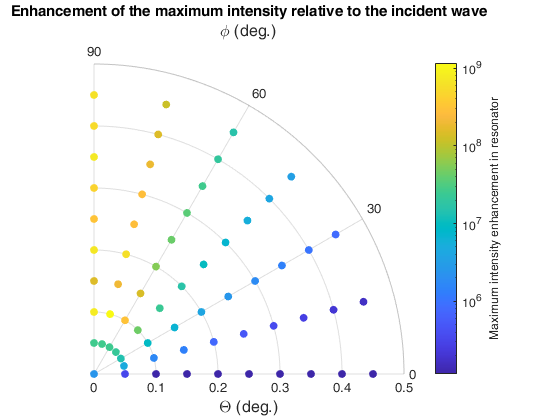

    case "2"
        options = set_study("EWFD: Signal", options, case_num);
        

Change default parameter values.

        if set_parameters
            % The number of frequencies to calculate.  With my file the minimum
            % is two due to an inner solution.
            options.parameters("ind_max",:).Value = "2";
            
            options.parameters("lda_p",:).Value = "1550[nm]/2";
            options.parameters("lda_s",:).Value = "1548.9[nm]";
            options.parameters("lda_s_max",:).Value = "1548.97[nm]";
            options.parameters("ind_max",:).Value = "71";
        end
        

### Example of a sweep over all combinations of values

    case "3"
        options = set_study("EWFD: Signal", options, case_num);
        

Definition of the sweep

        ParameterName = ["orientation_xy"; "phi"];
        theta_values = get_range("step", 0, 0.1, 1, "[deg]");
        phi_values = ["0[deg]","90[deg]"];
        
        Value = allcomb(theta_values, phi_values);
        options.sweep = table(ParameterName, Value); 
        options.sweep_output_dirs = get_sweep_dirs(options.sweep, options);
        

Change default parameter values.

        if set_parameters
            % The number of frequencies to calculate.  With my file the minimum
            % is two due to an inner solution.
            options.parameters("ind_max",:).Value = "2";
            
            options.parameters("lda_p",:).Value = "1550[nm]/2";
            options.parameters("lda_s",:).Value = "1548.9[nm]";
            options.parameters("lda_s_max",:).Value = "1548.97[nm]";
            options.parameters("ind_max",:).Value = "71";
        end
        

### Example of a sweep over specified values

    case "3"
        options = set_study("EWFD: Signal", options, case_num);
        

Definition of the sweep

    ParameterName = ["theta"; "phi"; "pol_p_idler"; "pol_s_idler"; "orientation"];
    Value = ["0",   "0",   "0",       "0",       "0",       "0";...       % theta
             "0",   "0",   "45[deg]", "0",       "0",       "45[deg]";... % phi
             "1",   "0",   "1",       "1",       "0",       "1";...       % pol_p_idler
             "0",   "1",   "0",       "0",       "1",       "0";...       % pol_s_idler
             "111", "111", "111",     "110",     "110",     "110"];       % orientation
    
    options.sweep = table(ParameterName, Value); 
    options.sweep_output_dirs = get_sweep_dirs(options.sweep, options);
    

Change default parameter values.

        if set_parameters
            % The number of frequencies to calculate.  With my file the minimum
            % is two due to an inner solution.
            options.parameters("ind_max",:).Value = "2";
            
            options.parameters("lda_p",:).Value = "1550[nm]/2";
            options.parameters("lda_s",:).Value = "1548.9[nm]";
            options.parameters("lda_s_max",:).Value = "1548.97[nm]";
            options.parameters("ind_max",:).Value = "71";
        end
        
    otherwise
            error(['Unknown configuration number in switch/case',...
                ' statement in setup_comsol.mlx\n']);
end

options.show_progress = true; % The COMSOL progress window
options.save_progress_log = false; % Large file!


function options = set_study(study_name, options, case_num)
    

Which study to run.

    options.study = study_name;
    options.mph_file.name = "sphere_v05_v5_3.mph";

Directory where the COMSOL files are kept - include trainling slash.

    options.mph_file.directory = 'D:\OneDrive - Australian National University\DFG_metasurfaces\Ghost Dimer\';

I have had some trouble with OneDrive placing locks on files, so first save the data to local disk only and then, after all processing, move it to OneDrive.

    options.base_data_dir = 'D:\Matthew\data\';
    options.base_data_dir_final = 'D:\OneDrive - Australian National University\data\COMSOL\';

Which functions to use

    options.mk_output_dirs = 'mk_output_dirs';
    options.post_processing = 'user_post_processing';
    options.mph_description = 'mph_description_auto';
    options.set_defaults = "set_default_options_auto";

## Parametric sweep

This is just a list of all of the parameters to be swept over as well as the value combinations.  This is the same as the "specified combinations" option in a parametric sweep in COMSOL.  To get an "all combinations" equivalent I need to write a function that will convert the specified lists of values into every possible combination to store here in the same way.  There should not be any overhead in using this rather than COMSOL's parameter sweeps.  The advantage of this system is that comsol can be rather flaky in whether or not it will export data after a sweep.  By doing the seep ourselves we can be assured that the exports will always be run.

No parametric sweep by default

    ParameterName = "";
    Value = "";
    options.sweep = table(ParameterName, Value);
    options.sweep_all_combinations = false;
    options.sweep_output_dirs = '';
    

## Directories

    options.output_dir = [options.base_data_dir 'sphere\spheres_'...
        matlab.lang.makeValidName(['case_' num2str(case_num)]) '\'];
    if ~isempty(options.base_data_dir_final)
        options.output_dir_final = [options.base_data_dir_final 'sphere\spheres_'...
            matlab.lang.makeValidName(['case_' num2str(case_num)]) '\'];
    else
        options.output_dir_final = '';
    end
end